# FacTRBGS versus FacTRBAGS experiments (Synthetic Data)

In this notebook, we are implementing tensor randomized Gauss Seidel for solving A*X = B, where A is given as a product of two tensors U and B, i.e., A is in **factorized** form. We compare the performances of factorized TRBGS **(with pseudoinverse**) and TRBAGS (**pseudoinverse free**).

We look at the cases of inconsistent (only), overdetermined and undertermined systems versus sampling block sizes.

clear
close all
clc

% If needed, add a local path where the tproduct toolbox is located
addpath('.../tproduct toolbox 2.0 (transform)/')

warning('off','all')

% Define a destination folder for the figures
figsdest = '.../Synthetic_Data/Figs_FacTRBGSvsFacTRBAGS';

% Set some universal (hyper)parameters
num_its = 100; % Number of iterations for all experiments
w_const = 1; % (Constant) weight value factor
weights_1 = w_const*ones(num_its,1);
weights_2 = w_const*ones(num_its,1);
num_runs = 1;

% Set some figures options
line_styles = {'b-','r--','k-.','c:','g-o'};
sep = 10;
method1 = 'facTRBGS';
method2 = 'facTRBAGS'; 
errtype1 = 'rel err';
errtype2 = 'res err';
sp = ' ';
legendStrings1 =  strcat(method1,sp,sp,errtype1);
legendStrings2 =  strcat(method1,sp,sp,errtype2);
legendStrings3 =  strcat(method2,sp,errtype1);
legendStrings4 =  strcat(method2,sp,errtype2);

## Case 1. U underdetermined (m < m_2) V underdetermined (m_1 > m_2), A underdetermined (m < m_1)

First, we'll generate a tensor linear system.

% Define tensor sizes; the following two are fixed
p = 30;
n = 10;

% Description of factors
% X_true is m x m_1 x p, in this case 20 x 10 x 30
% m determines whether A = UV is underdetermined or overdetermined
% m_1 determines whether V is underdetermined or overdetermined
% m_2 is like k in Ma & Needell's paper
% U underdetermined (m < m_2) V underdetermined (m_1 > m_2), A underdetermined (m < m_1)--Works
m_1 = 20;
m = 10;
m_2 = 15;

% Generate normally distributed pseudorandom tensors of sizes above, with A = tprod(U,V);
U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
X_true = randn(m_1,n,p);

% Generate consistent measurements
Z_ddagg = tprod(V,X_true);

%generate component in col(U)^perp
Y_tild = randn(m,n,p);
X_tild = tprod(tpinv(U),Y_tild);
Y_perp = Y_tild - tprod(U,X_tild);

% Generate consistent and inconsistent measurements
B_true = tprod(U,Z_ddagg);
B = B_true + 0.0001*Y_perp;

% Define initial iterate
X_0 = randn(size(X_true));

% Compute the least-norm solution 
X_ln = tprod(tpinv(V),Z_ddagg);

Now, we run FacTBRGS and FacTRBAGS with on this inconsistent system.

% Set block sizes; here, we kept the block size constant at 5
out_block_sizes = 5; %remember that the updates only make sense for block size <= number of columns
in_block_sizes = 5; %remember that the updates only make sense for block size <= number of columns

% Initializing the error vectors for facTRBGS
out_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
out_res_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
inner_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_inner_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
sum_res_ln_errs = res_inner_ln_errs;
ave_res_ln_errs = sum_res_ln_errs;

% Run the iterations for facTRBGS 
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,out_errs(i,:,k),out_res_ln_errs(i,:,k),inner_errs(i,:,k),res_inner_ln_errs(i,:,k)] = FacTRBGS_err(U,V,B,X_0,X_true,X_ln,num_its,out_block_size,in_block_size);
        end
        sum_res_ln_errs(:,:,k) = sum_res_ln_errs(:,:,k)+res_inner_ln_errs(:,:,k);
    end
    ave_res_ln_errs(:,:,k) = sum_res_ln_errs(:,:,k)/num_runs;
end

% Initializing the error vectors for FacTRBAGS
errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_ln_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
inner_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_inner_ln_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
sum_res_ln_errs_ave = res_inner_ln_errs_ave;
ave_res_ln_errs_ave = sum_res_ln_errs_ave;


% Run the iterations for FacTRBAGS
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,errs_ave(i,:,k),res_ln_errs_ave(i,:,k),inner_errs_ave(i,:,k),res_inner_ln_errs_ave(i,:,k)] = FacTRBAGS_err(U,V,B,X_0,X_true,X_ln,num_its,out_block_size,in_block_size, weights_1,weights_2);
        end
        sum_res_ln_errs_ave(:,:,k) = sum_res_ln_errs_ave(:,:,k)+res_inner_ln_errs_ave(:,:,k);
    end
    ave_res_ln_errs_ave(:,:,k) = sum_res_ln_errs_ave(:,:,k)/num_runs;
end

Next, we plot our results.

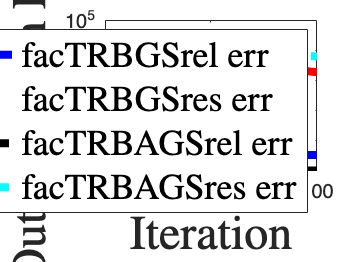

% Plot outer errors vs iterations for FacTRBAGS and FacTRBGS
figure()
set(gca,'FontSize',18)
semilogy(0:sep:num_its,out_errs(1,1:sep:num_its+1,1),line_styles{1},0:sep:num_its,out_res_ln_errs(1,1:sep:num_its+1,1),line_styles{2},0:sep:num_its,errs_ave(1,1:sep:num_its+1,1),line_styles{3},0:sep:num_its,res_ln_errs_ave(1,1:sep:num_its+1,1),line_styles{4},'LineWidth',4)
xlabel('Iteration','Interpreter','latex','FontSize',24)  
ylabel('Outer System Error','Interpreter','latex','FontSize',24) 
legend(legendStrings1,legendStrings2,legendStrings3,legendStrings4,'Interpreter','latex', 'FontSize',18);
filename = "outer_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".png";
filename_fig = "outer_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".fig";
saveas(gca,fullfile(figsdest,filename))

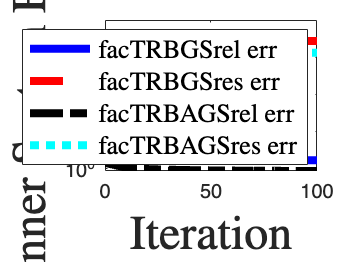

saveas(gca,fullfile(figsdest,filename_fig))

% Plot inner errors vs iterations for FacTRBAGS and FacTRBGS
figure();
set(gca,'FontSize',18)
semilogy(0:sep:num_its,inner_errs(1,1:sep:num_its+1,1),line_styles{1},0:sep:num_its,res_inner_ln_errs(1,1:sep:num_its+1,1),line_styles{2},0:sep:num_its,inner_errs_ave(1,1:sep:num_its+1,1),line_styles{3},0:sep:num_its,res_inner_ln_errs_ave(1,1:sep:num_its+1,1),line_styles{4},'LineWidth',4)
xlabel('Iteration','Interpreter','latex','FontSize',24) 
ylabel('Inner System Error','Interpreter','latex','FontSize',24) 
legend(legendStrings1,legendStrings2,legendStrings3,legendStrings4,'Interpreter','latex', 'FontSize',13);
filename = "inner_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".png";
filename_fig = "inner_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".fig";
saveas(gca,fullfile(figsdest,filename))

saveas(gca,fullfile(figsdest,filename_fig))

## Case 2. U overdetermined (m > m_2) V underdetermined (m_1 > m_2), A underdetermined (m < m_1)

First, we'll generate a tensor linear system.

% Define tensor sizes; the following two are fixed.
p = 30;
n = 10;

% Description of factors
% X_true is m x m_1 x p, in this case 20 x 10 x 30
% m determines whether A = UV is underdetermined or overdetermined
% m_1 determines whether V is underdetermined or overdetermined
% m_2 is like k in Ma & Needell's paper
% U overdetermined (m > m_2) V underdetermined (m_1 > m_2), A underdetermined (m < m_1)--Works
m_1 = 20;
m = 10;
m_2 = 5;

% Generate normally distributed pseudorandom tensors of sizes above, with A = tprod(U,V);
U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
X_true = randn(m_1,n,p);

% Generate consistent measurements
Z_ddagg = tprod(V,X_true);

% Generate component in col(U)^perp
Y_tild = randn(m,n,p);
X_tild = tprod(tpinv(U),Y_tild);
Y_perp = Y_tild - tprod(U,X_tild);

% Generate consistent and inconsistent measurements
B_true = tprod(U,Z_ddagg);
B = B_true + 0.0001*Y_perp;

% Define initial iterate
X_0 = randn(size(X_true));

% Compute the least-norm solution 
X_ln = tprod(tpinv(V),Z_ddagg);

Now, we run FacTBRGS and FacTRBAGS with on this inconsistent system.

% Set block sizes; here, we kept the block size constant at 5
out_block_sizes = 5; %remember that the updates only make sense for block size <= number of columns
in_block_sizes = 5; %remember that the updates only make sense for block size <= number of columns

% Initializing the error vectors for facTRBGS
out_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
out_res_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
inner_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_inner_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));

% Run the iterations for facTRBGS 
sum_res_ln_errs = res_inner_ln_errs;
ave_res_ln_errs = sum_res_ln_errs;
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,out_errs(i,:,k),out_res_ln_errs(i,:,k),inner_errs(i,:,k),res_inner_ln_errs(i,:,k)] = FacTRBGS_err(U,V,B,X_0,X_true,X_ln,num_its,out_block_size,in_block_size);
        end
        sum_res_ln_errs(:,:,k) = sum_res_ln_errs(:,:,k)+res_inner_ln_errs(:,:,k);
    end
    ave_res_ln_errs(:,:,k) = sum_res_ln_errs(:,:,k)/num_runs;
end

% Initializing the error vectors for facTRBAGS
errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_ln_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
inner_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_inner_ln_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));

% Run the iterations for facTRBGS 
sum_res_ln_errs_ave = res_inner_ln_errs_ave;
ave_res_ln_errs_ave = sum_res_ln_errs_ave;
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,errs_ave(i,:,k),res_ln_errs_ave(i,:,k),inner_errs_ave(i,:,k),res_inner_ln_errs_ave(i,:,k)] = FacTRBAGS_err(U,V,B,X_0,X_true,X_ln,num_its,out_block_size,in_block_size, weights_1,weights_2);
        end
        sum_res_ln_errs_ave(:,:,k) = sum_res_ln_errs_ave(:,:,k)+res_inner_ln_errs_ave(:,:,k);
    end
    ave_res_ln_errs_ave(:,:,k) = sum_res_ln_errs_ave(:,:,k)/num_runs;
end

Next, we plot our results.

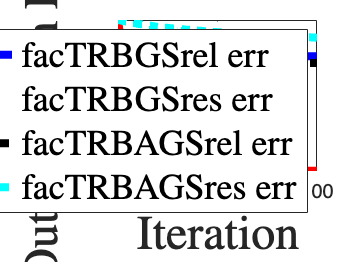

% Plot outer errors vs iterations for FacTRBAGS and FacTRBGS
figure()
set(gca,'FontSize',18)
semilogy(0:sep:num_its,out_errs(1,1:sep:num_its+1,1),line_styles{1},0:sep:num_its,out_res_ln_errs(1,1:sep:num_its+1,1),line_styles{2},0:sep:num_its,errs_ave(1,1:sep:num_its+1,1),line_styles{3},0:sep:num_its,res_ln_errs_ave(1,1:sep:num_its+1,1),line_styles{4},'LineWidth',4)
xlabel('Iteration','Interpreter','latex','FontSize',24)  
ylabel('Outer System Error','Interpreter','latex','FontSize',24) 
legend(legendStrings1,legendStrings2,legendStrings3,legendStrings4,'Interpreter','latex', 'FontSize',18);
filename = "outer_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".png";
filename_fig = "outer_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".fig";
saveas(gca,fullfile(figsdest,filename))

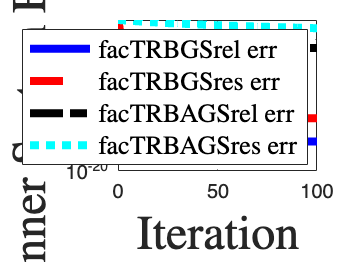

saveas(gca,fullfile(figsdest,filename_fig))

% Plot inner errors vs iterations for FacTRBAGS and FacTRBGS
figure();
set(gca,'FontSize',18)
semilogy(0:sep:num_its,inner_errs(1,1:sep:num_its+1,1),line_styles{1},0:sep:num_its,res_inner_ln_errs(1,1:sep:num_its+1,1),line_styles{2},0:sep:num_its,inner_errs_ave(1,1:sep:num_its+1,1),line_styles{3},0:sep:num_its,res_inner_ln_errs_ave(1,1:sep:num_its+1,1),line_styles{4},'LineWidth',4)
xlabel('Iteration','Interpreter','latex','FontSize',24) 
ylabel('Inner System Error','Interpreter','latex','FontSize',24) 
legend(legendStrings1,legendStrings2,legendStrings3,legendStrings4,'Interpreter','latex', 'FontSize',13);
filename = "inner_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".png";
filename_fig = "inner_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".fig";
saveas(gca,fullfile(figsdest,filename))

saveas(gca,fullfile(figsdest,filename_fig))

## Case 3. U underdetermined (m < m_2) V overdetermined (m_1 < m_2), A underdetermined (m < m_1)

First, we'll generate a tensor linear system.

% Define tensor size; the following two are fixed
p = 30;
n = 10;

% Description of factors
% X_true is m x m_1 x p, in this case 20 x 10 x 30
% m determines whether A = UV is underdetermined or overdetermined
% m_1 determines whether V is underdetermined or overdetermined
% m_2 is like k in Ma & Needell's paper
% U underdetermined (m < m_2) V overdetermined (m_1 < m_2), A underdetermined (m < m_1)--Works
m_1 = 20;
m = 10;
m_2 = 25;

% Generate normally distributed pseudorandom tensors of sizes above, with A = tprod(U,V);
U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
X_true = randn(m_1,n,p);

% Generate consistent measurements
Z_ddagg = tprod(V,X_true);

% Generate component in col(U)^perp
Y_tild = randn(m,n,p);
X_tild = tprod(tpinv(U),Y_tild);
Y_perp = Y_tild - tprod(U,X_tild);

% Generate consistent and inconsistent measurements
B_true = tprod(U,Z_ddagg);
B = B_true + 0.0001*Y_perp;

% Define initial iterate
X_0 = randn(size(X_true));

% Compute the least-norm solution 
X_ln = tprod(tpinv(V),Z_ddagg);

Now, we run FacTBRGS and FacTRBAGS with on this inconsistent system.

% Set block sizes; here, we kept the block size constant at 5
out_block_sizes = 5; %remember that the updates only make sense for block size <= number of columns
in_block_sizes = 5; %remember that the updates only make sense for block size <= number of columns

% Initializing the error vectors for facTRBGS
out_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
out_res_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
inner_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_inner_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
sum_res_ln_errs = res_inner_ln_errs;
ave_res_ln_errs = sum_res_ln_errs;

% Run the iterations for facTRBGS 
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,out_errs(i,:,k),out_res_ln_errs(i,:,k),inner_errs(i,:,k),res_inner_ln_errs(i,:,k)] = FacTRBGS_err(U,V,B,X_0,X_true,X_ln,num_its,out_block_size,in_block_size);
        end
        sum_res_ln_errs(:,:,k) = sum_res_ln_errs(:,:,k)+res_inner_ln_errs(:,:,k);
    end
    ave_res_ln_errs(:,:,k) = sum_res_ln_errs(:,:,k)/num_runs;
end

% Initializing the error vectors for facTRBAGS
errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_ln_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
inner_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_inner_ln_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
sum_res_ln_errs_ave = res_inner_ln_errs_ave;
ave_res_ln_errs_ave = sum_res_ln_errs_ave;

% Run the iterations for facTRBAGS 
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,errs_ave(i,:,k),res_ln_errs_ave(i,:,k),inner_errs_ave(i,:,k),res_inner_ln_errs_ave(i,:,k)] = FacTRBAGS_err(U,V,B,X_0,X_true,X_ln,num_its,out_block_size,in_block_size, weights_1,weights_2);
        end
        sum_res_ln_errs_ave(:,:,k) = sum_res_ln_errs_ave(:,:,k)+res_inner_ln_errs_ave(:,:,k);
    end
    ave_res_ln_errs_ave(:,:,k) = sum_res_ln_errs_ave(:,:,k)/num_runs;
end

Next, we plot our results.

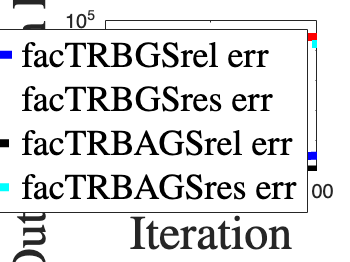

% Plot outer errors vs iterations for FacTRBAGS and FacTRBGS
figure()
set(gca,'FontSize',18)
semilogy(0:sep:num_its,out_errs(1,1:sep:num_its+1,1),line_styles{1},0:sep:num_its,out_res_ln_errs(1,1:sep:num_its+1,1),line_styles{2},0:sep:num_its,errs_ave(1,1:sep:num_its+1,1),line_styles{3},0:sep:num_its,res_ln_errs_ave(1,1:sep:num_its+1,1),line_styles{4},'LineWidth',4)
xlabel('Iteration','Interpreter','latex','FontSize',24)  
ylabel('Outer System Error','Interpreter','latex','FontSize',24) 
legend(legendStrings1,legendStrings2,legendStrings3,legendStrings4,'Interpreter','latex', 'FontSize',18);
filename = "outer_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".png";
filename_fig = "outer_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".fig";
saveas(gca,fullfile(figsdest,filename))

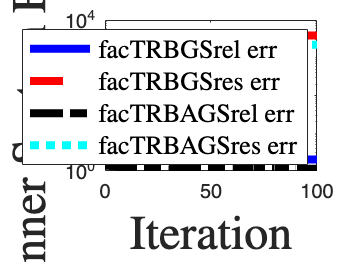

saveas(gca,fullfile(figsdest,filename_fig))

% Plot inner errors vs iterations for FacTRBAGS and FacTRBGS
figure();
set(gca,'FontSize',18)
semilogy(0:sep:num_its,inner_errs(1,1:sep:num_its+1,1),line_styles{1},0:sep:num_its,res_inner_ln_errs(1,1:sep:num_its+1,1),line_styles{2},0:sep:num_its,inner_errs_ave(1,1:sep:num_its+1,1),line_styles{3},0:sep:num_its,res_inner_ln_errs_ave(1,1:sep:num_its+1,1),line_styles{4},'LineWidth',4)
xlabel('Iteration','Interpreter','latex','FontSize',24) 
ylabel('Inner System Error','Interpreter','latex','FontSize',24) 
legend(legendStrings1,legendStrings2,legendStrings3,legendStrings4,'Interpreter','latex', 'FontSize',13);
filename = "inner_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".png";
filename_fig = "inner_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".fig";
saveas(gca,fullfile(figsdest,filename))

saveas(gca,fullfile(figsdest,filename_fig))

## Case 4. U overdetermined (m < m_2) V overdetermined (m_1 > m_2), A overdetermined (m > m_1)

% Define tensor size; the following two are fixed
p = 30;
n = 10;

% Description of factors
% X_true is m x m_1 x p, in this case 20 x 10 x 30
% m determines whether A = UV is underdetermined or overdetermined
% m_1 determines whether V is underdetermined or overdetermined
% m_2 is like k in Ma & Needell's paper
% U overdetermined (m < m_2) V overdetermined (m_1 > m_2), A overdetermined (m > m_1)--Works
m_1 = 20;
m = 30;
m_2 = 25;

% Generate normally distributed pseudorandom tensors of sizes above, with A = tprod(U,V);
U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
X_true = randn(m_1,n,p);

% Generate consistent measurements
Z_ddagg = tprod(V,X_true);

% Generate component in col(U)^perp
Y_tild = randn(m,n,p);
X_tild = tprod(tpinv(U),Y_tild);
Y_perp = Y_tild - tprod(U,X_tild);

% Generate consistent and inconsistent measurements
B_true = tprod(U,Z_ddagg);
B = B_true + 0.0001*Y_perp;

% Define initial iterate
X_0 = randn(size(X_true));

% Compute the least-norm solution 
X_ln = tprod(tpinv(V),Z_ddagg);

Now, we run FacTBRGS and FacTRBAGS with on this inconsistent system.

% Set block sizes; here, we kept the block size constant at 5
out_block_sizes = 5; %remember that the updates only make sense for block size <= number of columns
in_block_sizes = 5; %remember that the updates only make sense for block size <= number of columns

% Initializing the error vectors for facTRBGS
out_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
out_res_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
inner_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_inner_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
sum_res_ln_errs = res_inner_ln_errs;
ave_res_ln_errs = sum_res_ln_errs;

% Run the iterations for facTRBGS 
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,out_errs(i,:,k),out_res_ln_errs(i,:,k),inner_errs(i,:,k),res_inner_ln_errs(i,:,k)] = FacTRBGS_err(U,V,B,X_0,X_true,X_ln,num_its,out_block_size,in_block_size);
        end
        sum_res_ln_errs(:,:,k) = sum_res_ln_errs(:,:,k)+res_inner_ln_errs(:,:,k);
    end
    ave_res_ln_errs(:,:,k) = sum_res_ln_errs(:,:,k)/num_runs;
end

% Initializing the error vectors for facTRBAGS
errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_ln_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
inner_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_inner_ln_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
sum_res_ln_errs_ave = res_inner_ln_errs_ave;
ave_res_ln_errs_ave = sum_res_ln_errs_ave;

% Run the iterations for facTRBAGS 
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,errs_ave(i,:,k),res_ln_errs_ave(i,:,k),inner_errs_ave(i,:,k),res_inner_ln_errs_ave(i,:,k)] = FacTRBAGS_err(U,V,B,X_0,X_true,X_ln,num_its,out_block_size,in_block_size, weights_1,weights_2);
        end
        sum_res_ln_errs_ave(:,:,k) = sum_res_ln_errs_ave(:,:,k)+res_inner_ln_errs_ave(:,:,k);
    end
    ave_res_ln_errs_ave(:,:,k) = sum_res_ln_errs_ave(:,:,k)/num_runs;
end

Next, we plot our results.

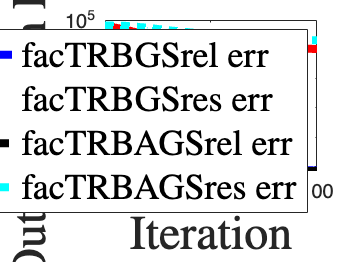

% Plot outer errors vs iterations for FacTRBAGS and FacTRBGS
figure()
set(gca,'FontSize',18)
semilogy(0:sep:num_its,out_errs(1,1:sep:num_its+1,1),line_styles{1},0:sep:num_its,out_res_ln_errs(1,1:sep:num_its+1,1),line_styles{2},0:sep:num_its,errs_ave(1,1:sep:num_its+1,1),line_styles{3},0:sep:num_its,res_ln_errs_ave(1,1:sep:num_its+1,1),line_styles{4},'LineWidth',4)
xlabel('Iteration','Interpreter','latex','FontSize',24)  
ylabel('Outer System Error','Interpreter','latex','FontSize',24) 
legend(legendStrings1,legendStrings2,legendStrings3,legendStrings4,'Interpreter','latex', 'FontSize',18);
filename = "outer_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".png";
filename_fig = "outer_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".fig";
saveas(gca,fullfile(figsdest,filename))

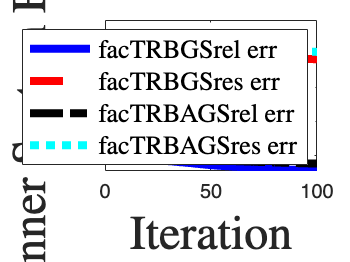

saveas(gca,fullfile(figsdest,filename_fig))

% Plot inner errors vs iterations for FacTRBAGS and FacTRBGS
figure();
set(gca,'FontSize',18)
semilogy(0:sep:num_its,inner_errs(1,1:sep:num_its+1,1),line_styles{1},0:sep:num_its,res_inner_ln_errs(1,1:sep:num_its+1,1),line_styles{2},0:sep:num_its,inner_errs_ave(1,1:sep:num_its+1,1),line_styles{3},0:sep:num_its,res_inner_ln_errs_ave(1,1:sep:num_its+1,1),line_styles{4},'LineWidth',4)
xlabel('Iteration','Interpreter','latex','FontSize',24) 
ylabel('Inner System Error','Interpreter','latex','FontSize',24) 
legend(legendStrings1,legendStrings2,legendStrings3,legendStrings4,'Interpreter','latex', 'FontSize',13);
filename = "inner_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".png";
filename_fig = "inner_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".fig";
saveas(gca,fullfile(figsdest,filename))

saveas(gca,fullfile(figsdest,filename_fig))

## Case 5. U overdetermined (m > m_2) V underdetermined (m_1 > m_2), A overdetermined (m > m_1)

% Define tensor size; the following two are fixed
p = 30;
n = 10;

% Description of factors
% X_true is m x m_1 x p, in this case 20 x 10 x 30
% m determines whether A = UV is underdetermined or overdetermined
% m_1 determines whether V is underdetermined or overdetermined
% m_2 is like k in Ma & Needell's paper
% U overdetermined (m > m_2) V underdetermined (m_1 > m_2), A overdetermined (m > m_1)--Works
m_1 = 20;
m = 30;
m_2 = 15;

% Generate normally distributed pseudorandom tensors of sizes above, with A = tprod(U,V);
U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
X_true = randn(m_1,n,p);

% Generate consistent measurements
Z_ddagg = tprod(V,X_true);

% Generate component in col(U)^perp
Y_tild = randn(m,n,p);
X_tild = tprod(tpinv(U),Y_tild);
Y_perp = Y_tild - tprod(U,X_tild);

% Generate consistent and inconsistent measurements
B_true = tprod(U,Z_ddagg);
B = B_true + 0.0001*Y_perp;

% Define initial iterate
X_0 = randn(size(X_true));

% Compute the least-norm solution 
X_ln = tprod(tpinv(V),Z_ddagg);

Now, we run FacTBRGS and FacTRBAGS with on this inconsistent system.

% Set block sizes; here, we kept the block size constant at 5
out_block_sizes = 5; %remember that the updates only make sense for block size <= number of columns
in_block_sizes = 5; %remember that the updates only make sense for block size <= number of columns

% Initializing the error vectors for facTRBGS
out_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
out_res_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
inner_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_inner_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
sum_res_ln_errs = res_inner_ln_errs;
ave_res_ln_errs = sum_res_ln_errs;

% Run the iterations for facTRBGS 
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,out_errs(i,:,k),out_res_ln_errs(i,:,k),inner_errs(i,:,k),res_inner_ln_errs(i,:,k)] = FacTRBGS_err(U,V,B,X_0,X_true,X_ln,num_its,out_block_size,in_block_size);
        end
        sum_res_ln_errs(:,:,k) = sum_res_ln_errs(:,:,k)+res_inner_ln_errs(:,:,k);
    end
    ave_res_ln_errs(:,:,k) = sum_res_ln_errs(:,:,k)/num_runs;
end

% Initializing the error vectors for facTRBAGS
errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_ln_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
inner_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_inner_ln_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
sum_res_ln_errs_ave = res_inner_ln_errs_ave;
ave_res_ln_errs_ave = sum_res_ln_errs_ave;

% Run the iterations for facTRBAGS 
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,errs_ave(i,:,k),res_ln_errs_ave(i,:,k),inner_errs_ave(i,:,k),res_inner_ln_errs_ave(i,:,k)] = FacTRBAGS_err(U,V,B,X_0,X_true,X_ln,num_its,out_block_size,in_block_size, weights_1,weights_2);
        end
        sum_res_ln_errs_ave(:,:,k) = sum_res_ln_errs_ave(:,:,k)+res_inner_ln_errs_ave(:,:,k);
    end
    ave_res_ln_errs_ave(:,:,k) = sum_res_ln_errs_ave(:,:,k)/num_runs;
end

Next, we plot our results.

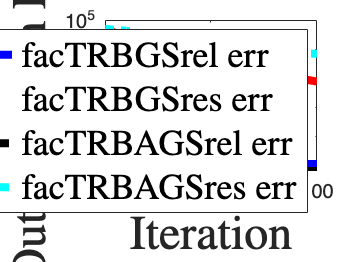

% Plot outer errors vs iterations for FacTRBAGS and FacTRBGS
figure()
set(gca,'FontSize',18)
semilogy(0:sep:num_its,out_errs(1,1:sep:num_its+1,1),line_styles{1},0:sep:num_its,out_res_ln_errs(1,1:sep:num_its+1,1),line_styles{2},0:sep:num_its,errs_ave(1,1:sep:num_its+1,1),line_styles{3},0:sep:num_its,res_ln_errs_ave(1,1:sep:num_its+1,1),line_styles{4},'LineWidth',4)
xlabel('Iteration','Interpreter','latex','FontSize',24)  
ylabel('Outer System Error','Interpreter','latex','FontSize',24) 
legend(legendStrings1,legendStrings2,legendStrings3,legendStrings4,'Interpreter','latex', 'FontSize',18);
filename = "outer_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".png";
filename_fig = "outer_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".fig";
saveas(gca,fullfile(figsdest,filename))

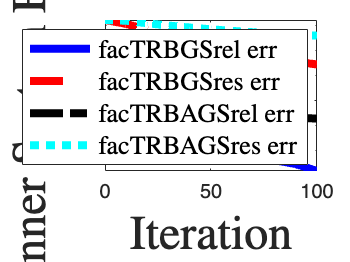

saveas(gca,fullfile(figsdest,filename_fig))

% Plot inner errors vs iterations for FacTRBAGS and FacTRBGS
figure();
set(gca,'FontSize',18)
semilogy(0:sep:num_its,inner_errs(1,1:sep:num_its+1,1),line_styles{1},0:sep:num_its,res_inner_ln_errs(1,1:sep:num_its+1,1),line_styles{2},0:sep:num_its,inner_errs_ave(1,1:sep:num_its+1,1),line_styles{3},0:sep:num_its,res_inner_ln_errs_ave(1,1:sep:num_its+1,1),line_styles{4},'LineWidth',4)
xlabel('Iteration','Interpreter','latex','FontSize',24) 
ylabel('Inner System Error','Interpreter','latex','FontSize',24) 
legend(legendStrings1,legendStrings2,legendStrings3,legendStrings4,'Interpreter','latex', 'FontSize',13);
filename = "inner_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".png";
filename_fig = "inner_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".fig";
saveas(gca,fullfile(figsdest,filename))

saveas(gca,fullfile(figsdest,filename_fig))

## Case 6. U underdetermined (m < m_2) V overdetermined (m_1 < m_2), A overdetermined (m > m_1)

% Define tensor size; the following two are fixed
p = 30;
n = 10;

% Description of factors
% X_true is m x m_1 x p, in this case 20 x 10 x 30
% m determines whether A = UV is underdetermined or overdetermined
% m_1 determines whether V is underdetermined or overdetermined
% m_2 is like k in Ma & Needell's paper
% U underdetermined (m < m_2) V overdetermined (m_1 < m_2), A overdetermined (m > m_1)--Works
m_1 = 20;

m = 30;
m_2 = 35;

% Generate normally distributed pseudorandom tensors of sizes above, with A = tprod(U,V);
U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
X_true = randn(m_1,n,p);

% Generate consistent measurements
Z_ddagg = tprod(V,X_true);

% Generate component in col(U)^perp
Y_tild = randn(m,n,p);
X_tild = tprod(tpinv(U),Y_tild);
Y_perp = Y_tild - tprod(U,X_tild);

% Generate consistent and inconsistent measurements
B_true = tprod(U,Z_ddagg);
B = B_true + 0.0001*Y_perp;

% Define initial iterate
X_0 = randn(size(X_true));

% Compute the least-norm solution 
X_ln = tprod(tpinv(V),Z_ddagg);

Now, we run FacTBRGS and FacTRBAGS with on this inconsistent system.

% Set block sizes; here, we kept the block size constant at 5
out_block_sizes = 5; %remember that the updates only make sense for block size <= number of columns
in_block_sizes = 5; %remember that the updates only make sense for block size <= number of columns

% Initializing the error vectors for facTRBGS
out_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
out_res_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
inner_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_inner_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
sum_res_ln_errs = res_inner_ln_errs;
ave_res_ln_errs = sum_res_ln_errs;

% Run the iterations for facTRBGS 
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,out_errs(i,:,k),out_res_ln_errs(i,:,k),inner_errs(i,:,k),res_inner_ln_errs(i,:,k)] = FacTRBGS_err(U,V,B,X_0,X_true,X_ln,num_its,out_block_size,in_block_size);
        end
        sum_res_ln_errs(:,:,k) = sum_res_ln_errs(:,:,k)+res_inner_ln_errs(:,:,k);
    end
    ave_res_ln_errs(:,:,k) = sum_res_ln_errs(:,:,k)/num_runs;
end

% Initializing the error vectors for facTRBAGS
errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_ln_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
inner_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_inner_ln_errs_ave = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
sum_res_ln_errs_ave = res_inner_ln_errs_ave;
ave_res_ln_errs_ave = sum_res_ln_errs_ave;

% Run the iterations for facTRBAGS 
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,errs_ave(i,:,k),res_ln_errs_ave(i,:,k),inner_errs_ave(i,:,k),res_inner_ln_errs_ave(i,:,k)] = FacTRBAGS_err(U,V,B,X_0,X_true,X_ln,num_its,out_block_size,in_block_size, weights_1,weights_2);
        end
        sum_res_ln_errs_ave(:,:,k) = sum_res_ln_errs_ave(:,:,k)+res_inner_ln_errs_ave(:,:,k);
    end
    ave_res_ln_errs_ave(:,:,k) = sum_res_ln_errs_ave(:,:,k)/num_runs;
end

Next, we plot our results.

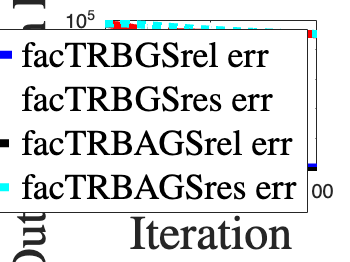

% Plot outer errors vs iterations for FacTRBAGS and FacTRBGS
figure()
set(gca,'FontSize',18)
semilogy(0:sep:num_its,out_errs(1,1:sep:num_its+1,1),line_styles{1},0:sep:num_its,out_res_ln_errs(1,1:sep:num_its+1,1),line_styles{2},0:sep:num_its,errs_ave(1,1:sep:num_its+1,1),line_styles{3},0:sep:num_its,res_ln_errs_ave(1,1:sep:num_its+1,1),line_styles{4},'LineWidth',4)
xlabel('Iteration','Interpreter','latex','FontSize',24)  
ylabel('Outer System Error','Interpreter','latex','FontSize',24) 
legend(legendStrings1,legendStrings2,legendStrings3,legendStrings4,'Interpreter','latex', 'FontSize',18);
filename = "outer_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".png";
filename_fig = "outer_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".fig";
saveas(gca,fullfile(figsdest,filename))

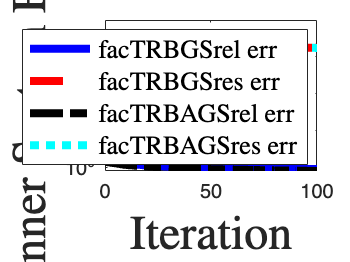

saveas(gca,fullfile(figsdest,filename_fig))

% Plot inner errors vs iterations for FacTRBAGS and FacTRBGS
figure();
set(gca,'FontSize',18)
semilogy(0:sep:num_its,inner_errs(1,1:sep:num_its+1,1),line_styles{1},0:sep:num_its,res_inner_ln_errs(1,1:sep:num_its+1,1),line_styles{2},0:sep:num_its,inner_errs_ave(1,1:sep:num_its+1,1),line_styles{3},0:sep:num_its,res_inner_ln_errs_ave(1,1:sep:num_its+1,1),line_styles{4},'LineWidth',4)
xlabel('Iteration','Interpreter','latex','FontSize',24) 
ylabel('Inner System Error','Interpreter','latex','FontSize',24) 
legend(legendStrings1,legendStrings2,legendStrings3,legendStrings4,'Interpreter','latex', 'FontSize',13);
filename = "inner_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".png";
filename_fig = "inner_FacTBRGS_FacTRBAGS_Ex"+get(gcf,'Number')+".fig";
saveas(gca,fullfile(figsdest,filename))

saveas(gca,fullfile(figsdest,filename_fig))